# Model wavefronts for DR01_54_HTI sample

**Author**: Abakumov Ivan

**Publication date**: 21st March 2018

**E-mail**: abakumov_ivan@mail.ru

## Introduction

`This script illustrates how to run FSM2DTTI eikonal solver`

## Define MLIB folder

clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;

## Problem:

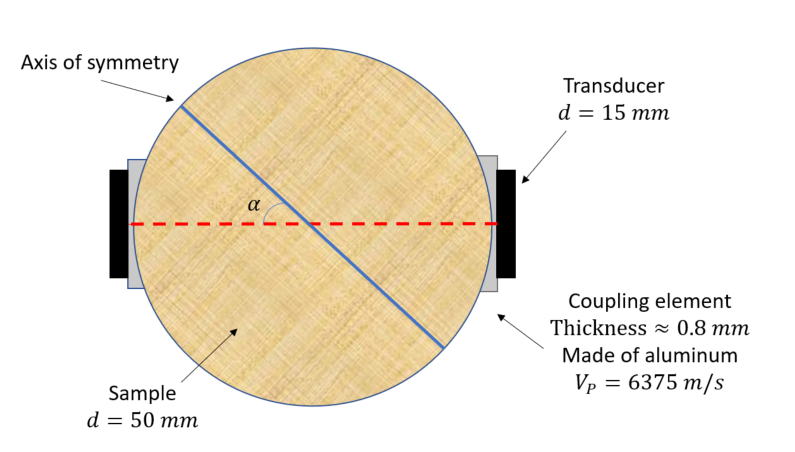

1) Model wavefronts as a function in the sample as a function of rotation angle

2) Model the effect of coupling element

3) Model the effect of Transducer on the recorded wavefield 

## Define grid

Create Grid file

For 2D codes only "x" and "z" fields are important

G=GridClass;

%    [mm]      [mm]       [mm]          [s]
G.x0=-27.5;  G.y0=0;    G.z0=-27.5;     G.t0 = 0.00;            % initial point
G.nx=1101;   G.ny=1;    G.nz=1101;      G.nt = 1000;             % grid size
G.dx=0.05;   G.dy=0;    G.dz=0.05;      G.dt = 0.01;           % grid step (meter)

G.gridInfo;

Information about grid:
x0=-27.5, dx=0.05, Nx=1101.
y0=0, dy=0, Ny=1.
z0=-27.5, dz=0.05, Nz=1101.
t0=0, dt=0.01, Nt=1000.


G.setGrid;

## Define velocity model

% Sample DR01-54-HTI
Sample.C11 = 63.3425*1e9; 
Sample.C33 = 51.9720*1e9;
Sample.C44 = 20.4813*1e9;
Sample.rho = 2507;
Sample.Vp0 = sqrt(Sample.C33/Sample.rho);
Sample.Vs0 = sqrt(Sample.C44/Sample.rho);
Sample.Epsilon = (Sample.C11 - Sample.C33)/(2*Sample.C33);
Sample.Delta = 0.124;
Sample.Theta = 0:5:90; 

Vqp = get_Vqp_VTI(Sample,Sample.Delta);

% sound
Vp      = 3430*ones(G.nx,G.nz);  % speed of sound (make x10 times for stability)
Epsilon =   0*ones(G.nx,G.nz);
Delta   =   0*ones(G.nx,G.nz);
Alfa   =   0*ones(G.nx,G.nz);

% add aluminium coupling element
CE.minx = -26.8;   % 25 mm sample radius + 0.8 mm thickness of coupling element
CE.maxx =  26.8;         
CE.minz = -9;   % 12.5 mm coupling element radius
CE.maxz =  9;         
CE.gminx = x2grid(CE.minx,G.x0,G.dx,G.nx);
CE.gmaxx = x2grid(CE.maxx,G.x0,G.dx,G.nx);
CE.gminz = x2grid(CE.minz,G.z0,G.dz,G.nz);
CE.gmaxz = x2grid(CE.maxz,G.z0,G.dz,G.nz);
CE.gxx = CE.gminx:CE.gmaxx;
CE.gzz = CE.gminz:CE.gmaxz;

Vp(CE.gxx,CE.gzz) = 6375;  % speed of aluminium
Epsilon(CE.gxx,CE.gzz) = 0;
Delta(CE.gxx,CE.gzz)   = 0;
Alfa(CE.gxx,CE.gzz)  =  0;
%Vp(CE.gxx,CE.gzz) = Sample.Vp0;  % Vp of sample
%Epsilon(CE.gxx,CE.gzz) = Sample.Epsilon;
%Delta(CE.gxx,CE.gzz)   = Sample.Delta;
%  Alfa(CE.gxx,CE.gzz)  =  45;


% add sample
[XX, ZZ] = meshgrid(G.xx, G.zz);
Sind = sqrt(XX.^2 + ZZ.^2) <= 25;

Vp(Sind) = Sample.Vp0;  % Vp of sample
Epsilon(Sind) = Sample.Epsilon;
Delta(Sind)   = Sample.Delta;
Alfa(Sind)  =  45;

Tind = Vp > 3500; 

## Sefine source position S = [Sx, Sy, Sz]

Source is located at x = -12.8 mm and z from -7.5 mm to 7.5 mm

Receiver is located at x = +12.8 mm and z from -7.5 mm to 7.5 mm

Source.z = - 7.5:0.05:7.5;
Source.x = -25.8*ones(size(Source.z)); 
Receiver.z = - 7.5:0.05:7.5;
Receiver.x = 25.8*ones(size(Receiver.z)); 
Source.gx = x2grid(Source.x,G.x0,G.dx,G.nx);
Source.gz = x2grid(Source.z,G.z0,G.dz,G.nz);
Receiver.gx = x2grid(Receiver.x,G.x0,G.dx,G.nx);
Receiver.gz = x2grid(Receiver.z,G.z0,G.dz,G.nz);

## Plot velocity model

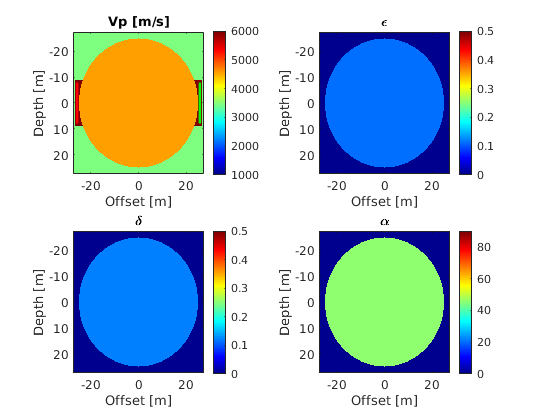

figure(11)
subplot(2,2,1)
imagesc(G.xx, G.zz, Vp'); 
colormap('jet')
colorbar;
xlabel('Offset [m]');
ylabel('Depth [m]');
title('Vp [m/s]')
caxis([1000 6000])
hold on 
plot(Source.x,Source.z, '.r')
plot(Receiver.x,Receiver.z, '.g')

subplot(2,2,2)
imagesc(G.xx, G.zz, Epsilon'); 
colormap('jet')
colorbar;
xlabel('Offset [m]');
ylabel('Depth [m]');
title('\epsilon')
caxis([0 0.5])

subplot(2,2,3)
imagesc(G.xx, G.zz, Delta'); 
colormap('jet')
colorbar;
xlabel('Offset [m]');
ylabel('Depth [m]');
title('\delta')
caxis([0 0.5])

subplot(2,2,4)
imagesc(G.xx, G.zz, Alfa'); 
colormap('jet')
colorbar;
xlabel('Offset [m]');
ylabel('Depth [m]');
title('\alpha')
caxis([0 90])

## Compute traveltimes with FSM2DTTI code

TTI = 1e20*ones(G.nx, G.nz, length(Source.x)); 

tic
for i = 1:length(Source.x)
    S = zeros(1,3);
    S(1) = Source.x(i);
    S(3) = Source.z(i);
    tti  = FSM2DTTI(G, S, Vp, Epsilon, Delta, Alfa);    
    TTI(:,:,i) = tti;
end
toc

Elapsed time is 1093.988256 seconds.



TTI = TTI*1000;         % convert to micro sec
sTTI = TTI(:,:,151);    % single sensor
mTTI = min(TTI,[],3);   % multiple sensors 

## Plot traveltimes and wavefronts

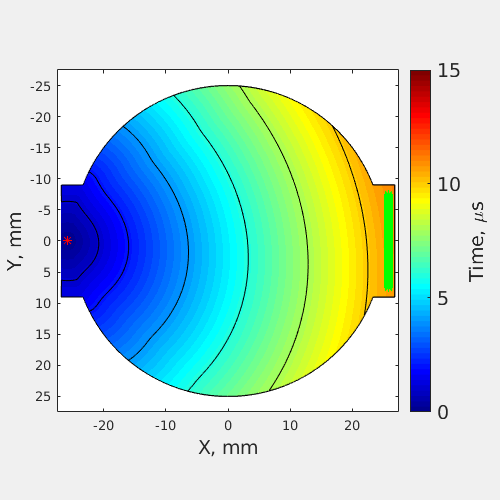

figure(44)
sTTI(~Tind) = 0; 
fig = figure('Position', [1 1 500 500]);
fig.Color = [240/255 240/255 240/255];
fig.InvertHardcopy = 'off'; 
h = pcolor(G.xx, G.zz, sTTI'); 
set(h,'alphadata',Tind','facealpha','flat','edgecolor','none');
shading interp
hold on 
contour(G.xx, G.zz, sTTI', [1 2 4 6 8 10], 'ShowText', 'off', 'Color', 'black')
xlabel('X, mm', 'FontSize', 14);
ylabel('Y, mm', 'FontSize', 14);
set(gca, 'YDir', 'reverse');
hold on 
plot(Source.x(151), Source.z(151), '*r'); 
plot(Receiver.x, Receiver.z, '*g'); 
axis equal;
caxis([0 15])
axis([G.x0,G.mx,G.z0,G.mz])
colormap('jet')
c = colorbar('eastoutside', 'Fontsize', 14);
c.Label.String = 'Time, \mus';
print(gcf, '/home/ivan/Desktop/figQ5.jpg', '-djpeg', '-r600');

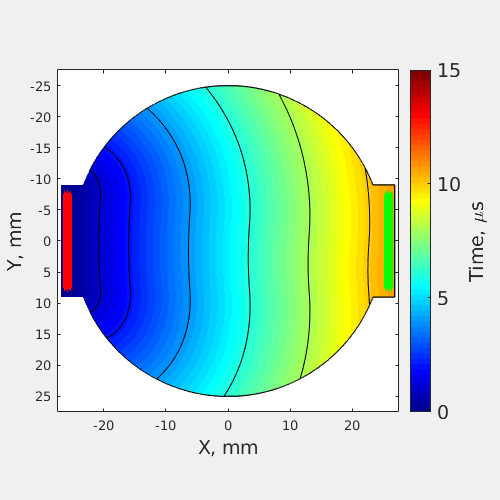

figure(46)
mTTI(~Tind) = 0; 
fig = figure('Position', [1 1 500 500]);
fig.Color = [240/255 240/255 240/255];
fig.InvertHardcopy = 'off'; 
h = pcolor(G.xx, G.zz, mTTI'); 
set(h,'alphadata',Tind','facealpha','flat','edgecolor','none');
shading interp
hold on 
contour(G.xx, G.zz, mTTI', [1 2 4 6 8 10], 'ShowText', 'off', 'Color', 'black')
xlabel('X, mm', 'FontSize', 14);
ylabel('Y, mm', 'FontSize', 14);
set(gca, 'YDir', 'reverse');
hold on 
plot(Source.x, Source.z, '*r'); 
plot(Receiver.x, Receiver.z, '*g'); 
axis equal;
caxis([0 15])
axis([G.x0,G.mx,G.z0,G.mz])
colormap('jet')
c = colorbar('eastoutside', 'Fontsize', 14);
c.Label.String = 'Time, \mus';
print(gcf, '/home/ivan/Desktop/figQ6.jpg', '-djpeg', '-r600');

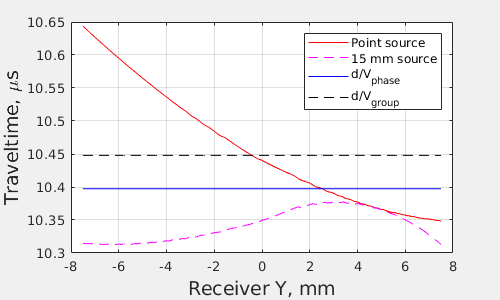

Theta = 0:1:90; 
Psi = get_psi_VTI(Sample,Sample.Delta,Theta);

psiq = 45; 
thetaq = interp1(Psi,Theta,psiq,'pchip');

newSample = Sample; 
newSample.Theta = psiq; 
Vphase = get_Vqp_VTI(newSample,newSample.Delta);
dtheta = 0.001; 
thetaq = 42.16; 
newSample.Theta = thetaq+dtheta; 
Vp = get_Vqp_VTI(newSample,newSample.Delta);

newSample.Theta = thetaq-dtheta; 
Vm = get_Vqp_VTI(newSample,newSample.Delta);

V = (Vp + Vm)/2; 
dV = (Vp - Vm)/(2*dtheta); 
Vgroup = sqrt(V^2 + dV^2);



%Vphase = Sample.Vp0; 
%Vgroup = Sample.Vp0; 

%TT.phase = (51.6)/Vphase*1000*ones(size(Receiver.x)); 
%TT.group = (51.6)/Vgroup*1000*ones(size(Receiver.x)); 
TT.phase = (50)/Vphase*1000*ones(size(Receiver.x)); 
TT.group = (50)/Vgroup*1000*ones(size(Receiver.x)); 

TT.ssens = sTTI(Receiver.gx(1), Receiver.gz); 
TT.msens = mTTI(Receiver.gx(1), Receiver.gz); 

% correction traveltime - traveltime in Al sample
% dtcorr = 1.6 mm / Val 
dtcorr = 0.0016/6375*1e6;  % mus
%  dtcorr = 0; 

figure(1); 
fig = figure('Position', [1 1 500 300]);
fig.Color = [240/255 240/255 240/255];
fig.InvertHardcopy = 'off'; 
plot(Receiver.z, TT.ssens-dtcorr, 'r');
hold on 
plot(Receiver.z, TT.msens-dtcorr, 'm--');
plot(Receiver.z, TT.phase, 'b') 
plot(Receiver.z, TT.group, 'k--') 
grid on
legend('Point source', '15 mm source', 'd/V_{phase}', 'd/V_{group}')
xlabel('Receiver Y, mm', 'FontSize', 14);
ylabel('Traveltime, \mus', 'FontSize', 14);
%axis([-7.5 7.5 11.3 11.5])
%axis([-7.5 7.5 10.7 11.1])
print(gcf, '/home/ivan/Desktop/figQ7.jpg', '-djpeg', '-r600');

% alpha = 0:5:90; 
% for i=1:length(alpha)
%     Alfa(CE.gxx,CE.gzz)  =  alpha(i);
%     Alfa(Sind) = alpha(i);
%     TT(i) = get_TT_model(G, Vp, Epsilon, Delta, Alfa, Tind, Source, Receiver)
% end 
% 
% 
% for i =1:19 
%     ttm(i) = mean(TT(i).msens(1:25:301)); 
% end

## Simulate the signal

f = 1; % MHz
signal = ricker(f, G.tt); 

dtm = TT.msens -dtcorr - TT.phase(1); 
dts = TT.ssens -dtcorr - TT.phase(1); 

  
Msignal2D = zeros(size(signal));
Msignal3D = zeros(size(signal));


[XX, ZZ] = meshgrid(-7.5:0.05:7.5,-7.5:0.05:7.5); 
ind = sqrt(XX.^2 + ZZ.^2) <= 7.5; 

% take 2D effect into account
for i=1:301
    msignal = add_time_shift_fft(signal,dtm(i)*100,f);
    Msignal2D = Msignal2D +msignal; 
end

% take 3D effect into account
for j=1:301
    cutTTI = TTI(:,:,ind(j,:));
    cTTI = min(cutTTI,[],3); 
    TT.csens = cTTI(Receiver.gx(1), Receiver.gz); 
    dtc = TT.csens -dtcorr - TT.phase(1); 
    for i=1:301
        if ind(j,i)==1
            msignal = add_time_shift_fft(signal,dtc(i)*100,f);
            Msignal3D = Msignal3D +msignal; 
        end
    end
    disp(j)
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

   101

   102

   103

   104

   105

   106

   107

   108

   109

   110

   111

   112

   113

   114

   115

   116

   117

   118

   119

   120

   121

   122

   123

   124

   125



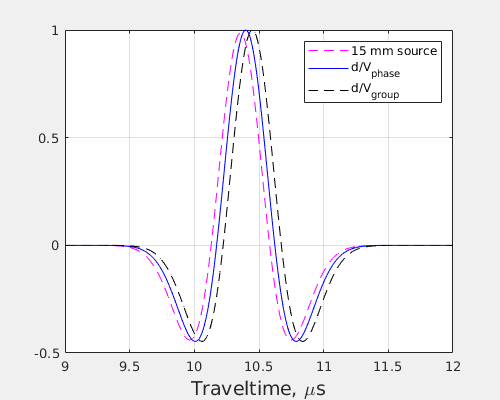

figure(58745)
fig = figure('Position', [1 1 500 400]);
fig.Color = [240/255 240/255 240/255];
fig.InvertHardcopy = 'off'; 
plot(G.tt + TT.phase(1) - 1.5, Msignal3D/sum(ind(:)), 'm--')
hold on
plot(G.tt + TT.phase(1) - 1.5, signal, 'b')
hold on 
plot(G.tt + TT.group(1) - 1.5, signal, 'k--')
axis([9 12 -0.5 1])
xlabel('Traveltime, \mus', 'FontSize', 14);
grid('on')
legend('15 mm source', 'd/V_{phase}', 'd/V_{group}')
print(gcf, '/home/ivan/Desktop/fig22.jpg', '-djpeg', '-r600')